# **Actividad: Raíces de Ecuaciones**

Diego Alejandro Espejo López A01638341

function biseccion(xi,xs,f,tol,num_it)
    f = str2func(strcat("@(x)", f));
    xa = (xi + xs) / 2;
    if f(xi)*f(xs) < 0 
        error = 100;
        i = 1;
        while (error > tol) && (i < num_it) && (f(xa) ~= 0)
            if f(xi) * f(xa) < 0
                xs = xa;
            else
                xi = xa;
            end
            xa_anterior = xa;
            xa = (xi + xs) / 2;
            
            % Condiciones
            i = i + 1;
            error = abs((xa - xa_anterior) / xa) * 100;
        end
        fprintf("Número de Iteraciones: %i\n", i);
        fprintf("Error: %f\n", error);
        fprintf("Raíz de la función: %f\n", xa);
    else
        disp("No existe raíz en el intervalo dado")
    end
    raiz = xa;
end

function newton_raphson(xi, f, tol, max_it)
    f = str2func(strcat("@(x)", f));
    syms x
    df = inline(diff(f, x));
    xa = xi - (f(xi) / df(xi));
    error = abs((xa - xi) / xa) * 100;

    i = 1;
    while (f(xa) ~= 0) && (error > tol) && (i < max_it) && (df(xa) ~= 0)
        xi = xa;
        xa = xi - (f(xi) / df(xi));
        error = abs((xa - xi) / xa) * 100;
        i = i + 1;
    end
    fprintf("Número de Iteraciones: %i\n", i);
    fprintf("Error: %f\n", error);
    fprintf("Raíz de la función: %f\n", xa);
    raiz = xa;
end

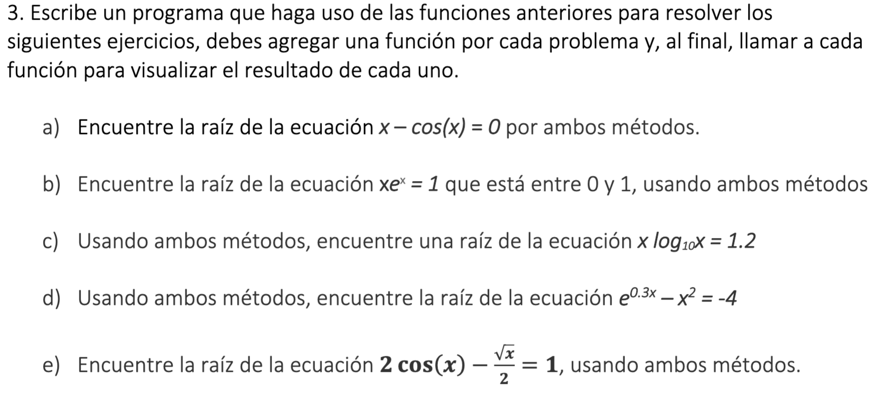


$$\left.a\right)\;x-\cos \left(x\right)=0$$


clear; clc;

f = "x-cos(x)";
xi = 0;
xs = 10;
tol = .001;
max_it = 50;

fprintf("Ejercicio 1")

Ejercicio 1

fprintf("Método de Bisección: ")

Método de Bisección: 

biseccion(xi,xs,f,tol,max_it)

Número de Iteraciones: 21
Error: 0.000645
Raíz de la función: 0.739083



fprintf("Método Newton-Raphson: ")

Método Newton-Raphson: 

newton_raphson(xi, f, tol, max_it)

Número de Iteraciones: 5
Error: 0.000000
Raíz de la función: 0.739085



$$\left.b\right)\;xe^x =1;0\;y\;1$$


clear; clc;

f = "x * exp(x)-1";
xi = 0;
xs = 1;
tol = .001;
max_it = 50;

fprintf("Ejercicio 2")

Ejercicio 2

fprintf("Método de Bisección: ")

Método de Bisección: 

biseccion(xi,xs,f,tol,max_it)

Número de Iteraciones: 18
Error: 0.000673
Raíz de la función: 0.567142



fprintf("Método Newton-Raphson: ")

Método Newton-Raphson: 

newton_raphson(xi, f, tol, max_it)

Número de Iteraciones: 6
Error: 0.000001
Raíz de la función: 0.567143



$$\left.c\right)\;x\log_{10} x=1\ldotp 2$$


clear; clc;

f = "x * log10(x) - 1.2";
xi = 1;
xs = 10;
tol = .001;
max_it = 50;

fprintf("Ejercicio 3")

Ejercicio 3

fprintf("Método de Bisección: ")

Método de Bisección: 

biseccion(xi,xs,f,tol,max_it)

Número de Iteraciones: 19
Error: 0.000626
Raíz de la función: 2.740629



fprintf("Método Newton-Raphson: ")

Método Newton-Raphson: 

newton_raphson(xi, f, tol, max_it)

Número de Iteraciones: 5
Error: 0.000000
Raíz de la función: 2.740646



$$\left.d\right)\;e^{0\ldotp 3x} -x^2 =-4$$


clear; clc;

f = "exp(0.3 * x) - x^2 + 4";
xi = 0;
xs = 10;
tol = .001;
max_it = 50;

fprintf("Ejercicio 4")

Ejercicio 4

fprintf("Método de Bisección: ")

Método de Bisección: 

biseccion(xi,xs,f,tol,max_it)

Número de Iteraciones: 19
Error: 0.000772
Raíz de la función: 2.469349



fprintf("Método Newton-Raphson: ")

Método Newton-Raphson: 

newton_raphson(xi, f, tol, max_it)

Número de Iteraciones: 8
Error: 0.000008
Raíz de la función: -2.127944



$$\left.e\right)\;2\cos \left(x\right)-\frac{\sqrt{x}}{2}=1$$


clear; clc;

f = "2*cos(x) - (sqrt(x)/2) - 1";
xi = 0;
xs = 10;
tol = .001;
max_it = 50;

fprintf("Ejercicio 5")

Ejercicio 5

fprintf("Método de Bisección: ")

Método de Bisección: 

biseccion(xi,xs,f,tol,max_it)

Número de Iteraciones: 21
Error: 0.000621
Raíz de la función: 0.768256



xi = 1;
xs = 10;
fprintf("Método Newton-Raphson: ")

Método Newton-Raphson: 

newton_raphson(xi, f, tol, max_it)

Número de Iteraciones: 4
Error: 0.000000
Raíz de la función: 0.768254
